# Experiment 2_3 (Wavelets)

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

### Part 1: generating a noisy signal

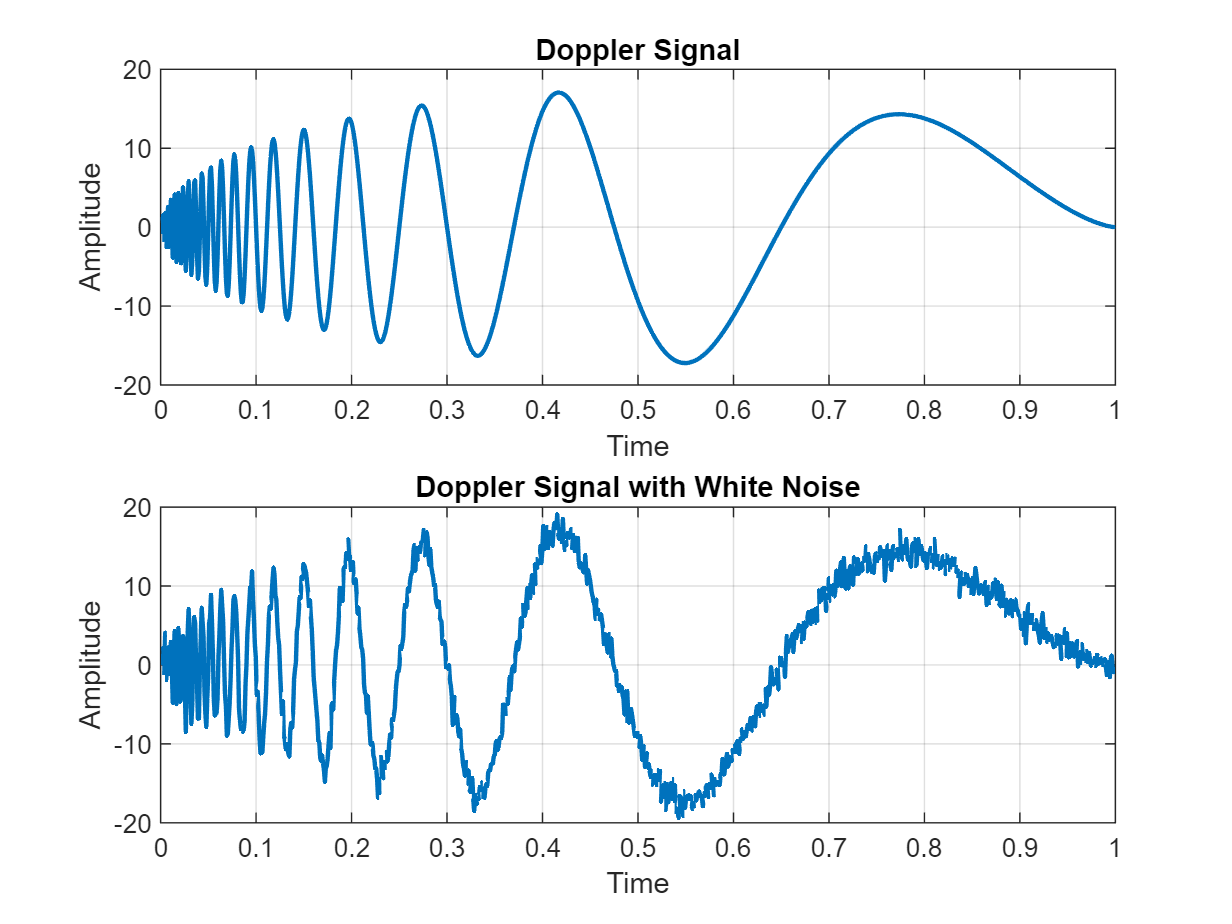

N = 10;
loc = linspace(0, 1, 2 ^ N);
Ts = loc(2) - loc(1);
fs = 1 / Ts;
sqrtsnr = 10;
[x, noisy_x] = wnoise("doppler", N, sqrtsnr);
figure("Name", "original and noisy signals");
subplot(211);
plot(loc, x, 'LineWidth', 1.5);
title('Doppler Signal');
xlabel('Time');
ylabel('Amplitude');
grid on;
subplot(212);
plot(loc, noisy_x, 'LineWidth', 1.5);
title('Doppler Signal with White Noise');
xlabel('Time');
ylabel('Amplitude');
grid on;

### Part 2: Plot Fourier Transform of x and noisy_x

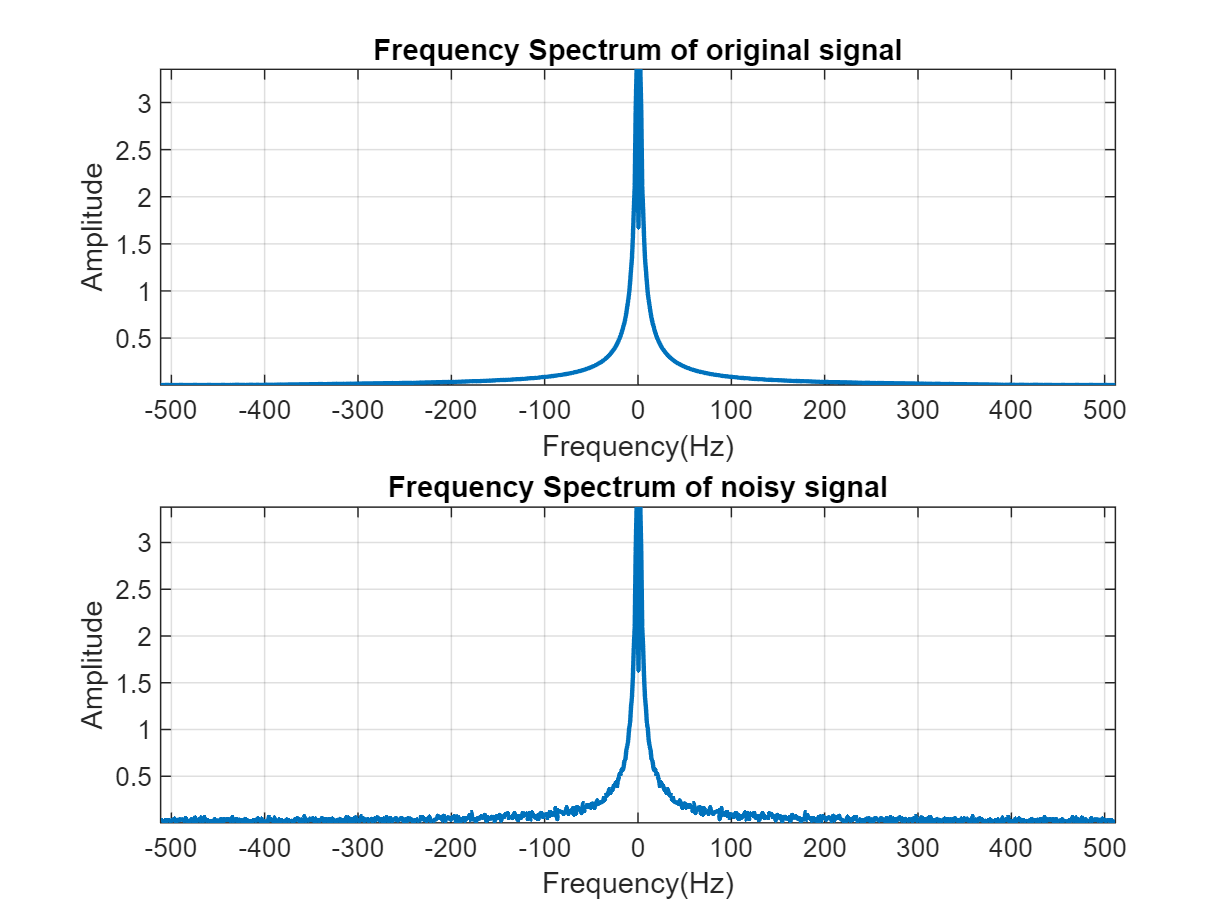

figure('Name', 'Spectrum of Heavy Sine Signal With and Without White Noise');
subplot(211);
plot_dft_amp(x, fs, 'Frequency Spectrum of original signal');
subplot(212);
plot_dft_amp(noisy_x, fs, 'Frequency Spectrum of noisy signal');

### Part 3: Plot Approximate coefficients and Detail coefficients using dwt

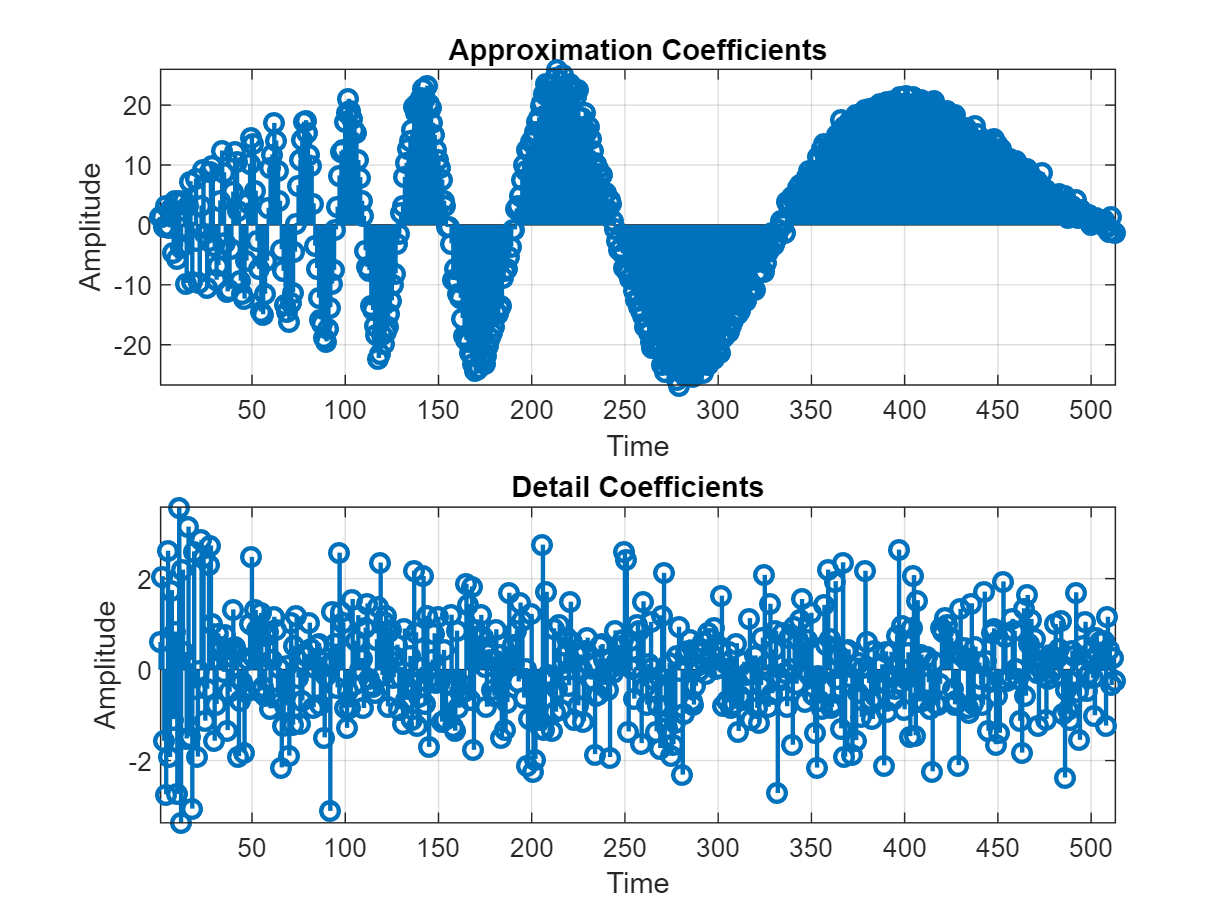

[cA, cD] = dwt(noisy_x, 'db2');
figure('Name', 'Approximation and Detail Coefficients');
subplot(211);
stem(cA, 'LineWidth', 1.5);
title('Approximation Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;
subplot(212);
stem(cD, 'LineWidth', 1.5);
title('Detail Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;

### Part 4: Perform wavedec function on noisy signal

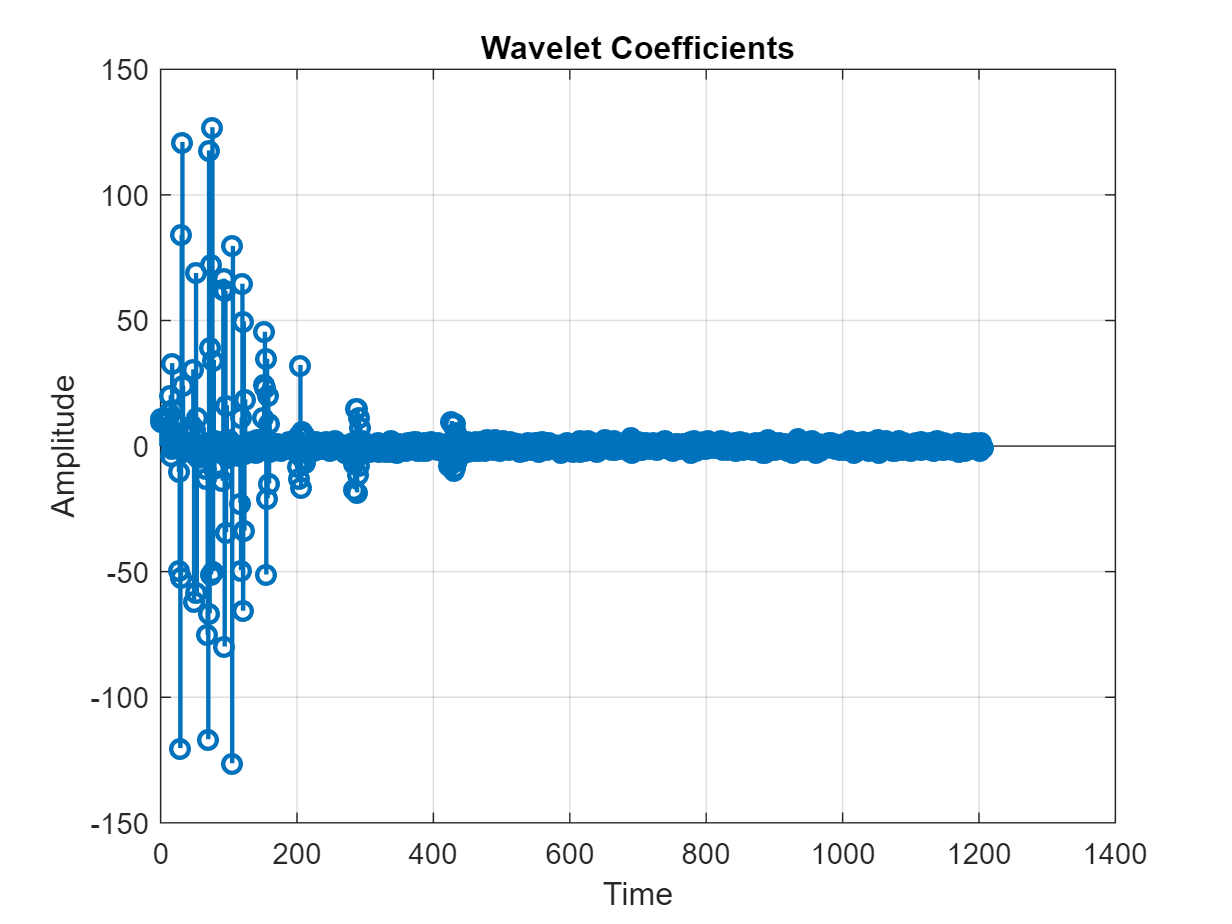

numberOfLevels = 10;
[waveletCoefficients, waveletLevels] = wavedec(noisy_x, numberOfLevels, 'db10');
figure('Name', 'Wavelet Coefficients');
stem(waveletCoefficients, 'LineWidth', 1.5);
title('Wavelet Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;

### Part 5: using detcoeff to extract detail coefficients

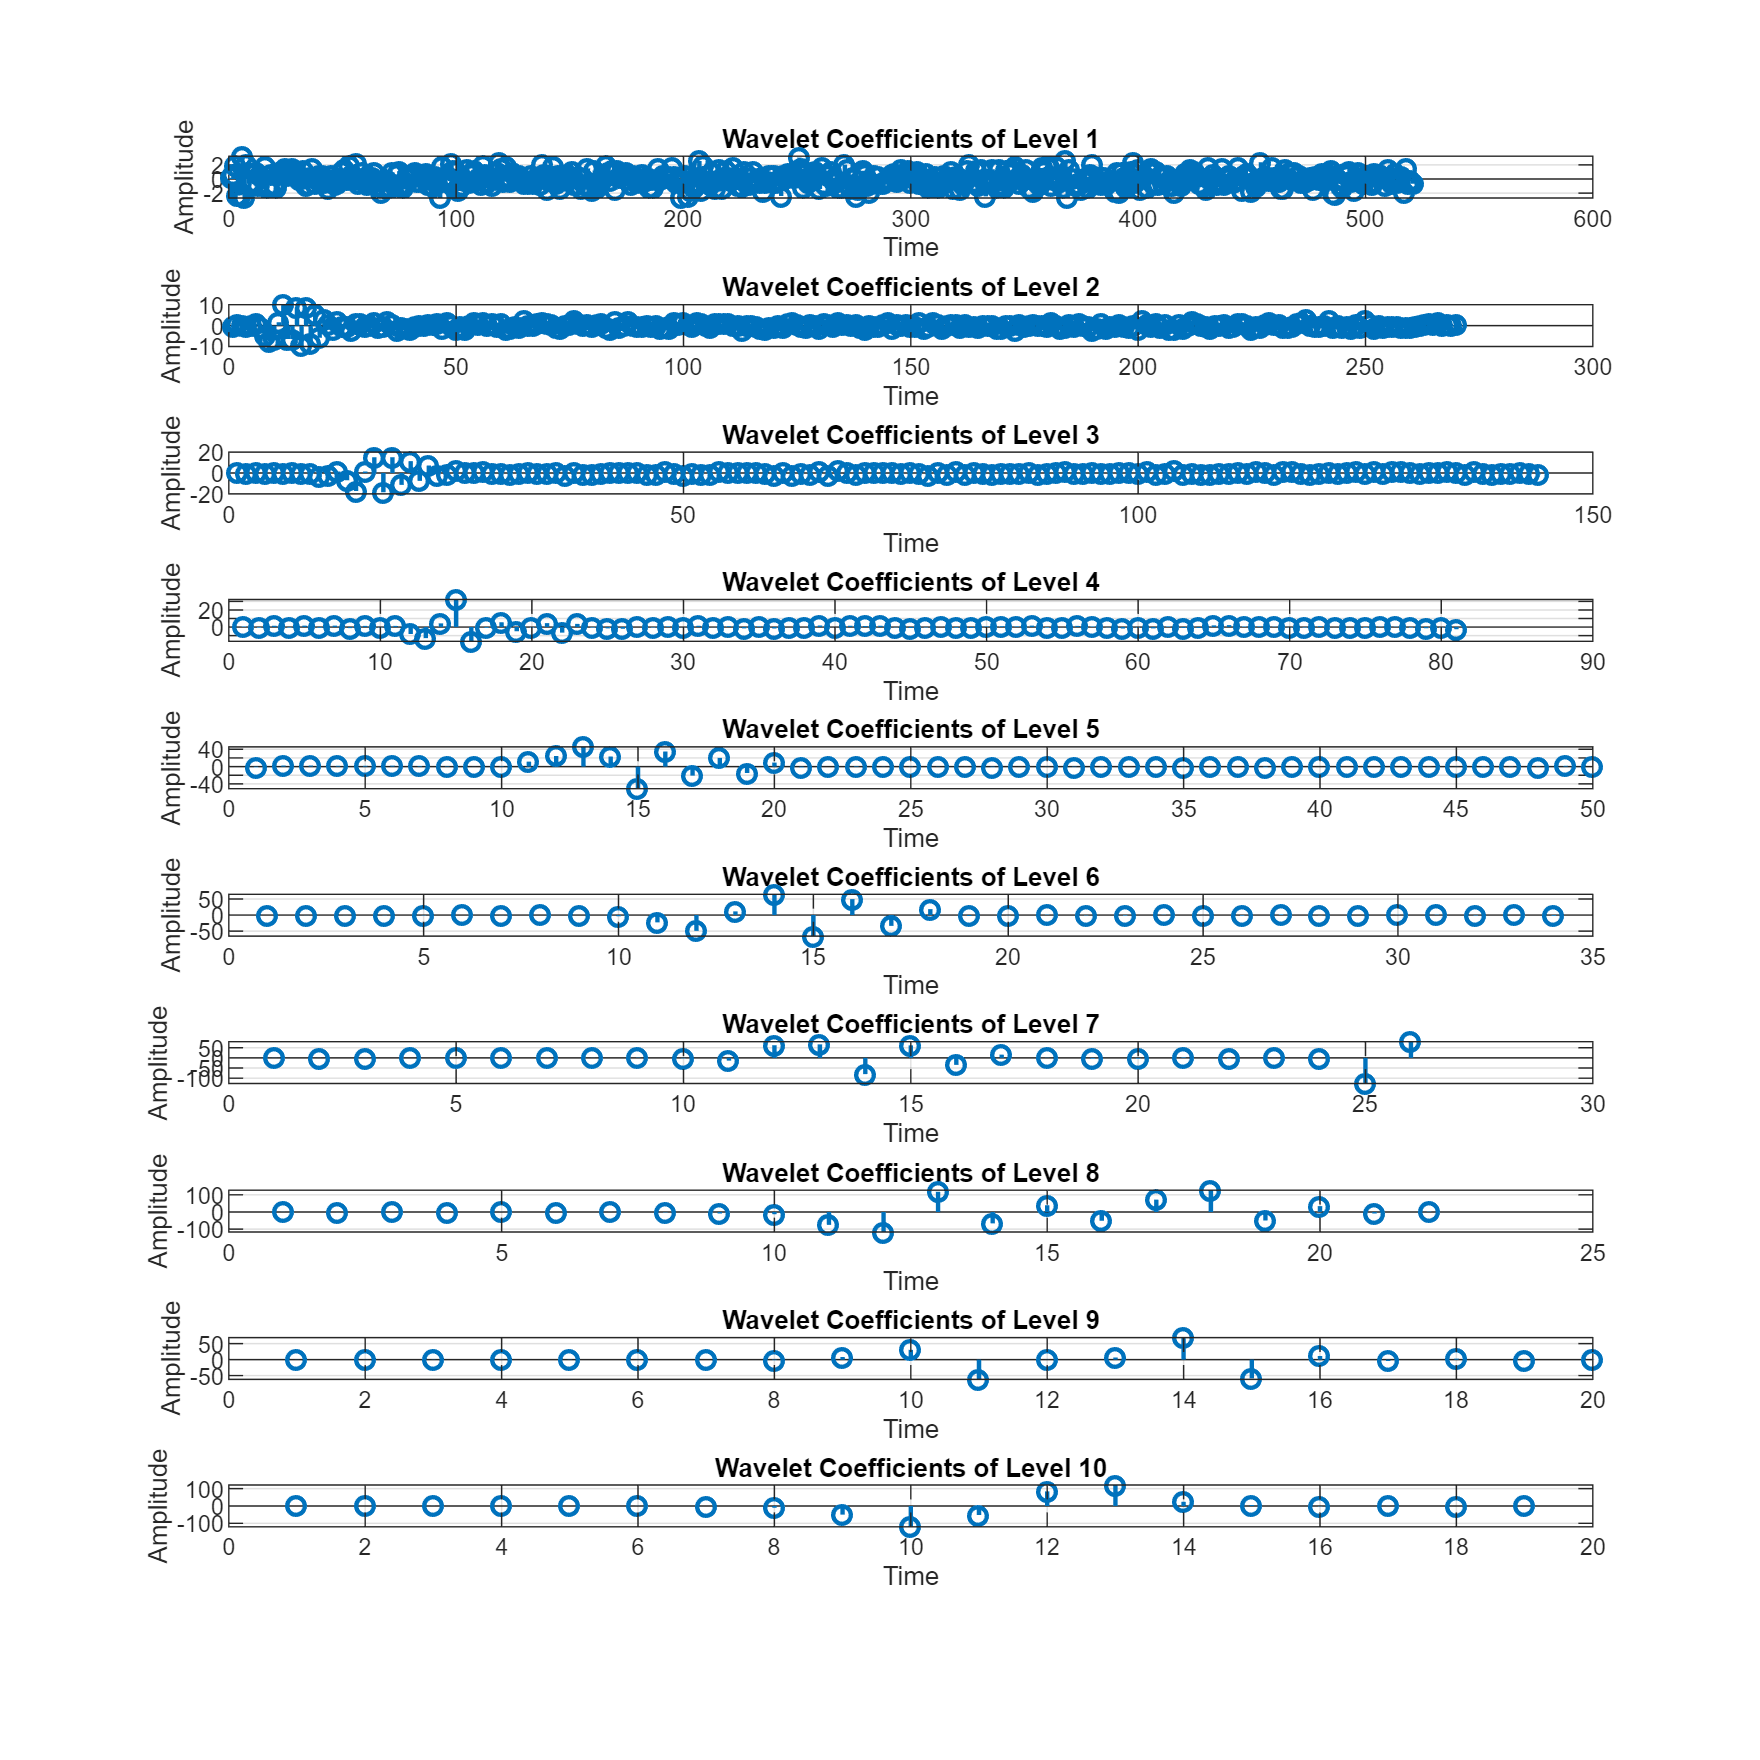

detailed_coeff = detcoef(waveletCoefficients, waveletLevels, 1:numberOfLevels);
figure('Name', 'Wavelet Coefficients of Different Levels');
set(gcf, 'Position', [100, 100, 1000, 1000]);

for i = 1:numberOfLevels
    subplot(numberOfLevels, 1, i);
    stem(detailed_coeff{i}, 'LineWidth', 1.5);
    title(['Wavelet Coefficients of Level ', num2str(i)]);
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

### Part 6: using appcoeff to extract detail coefficients

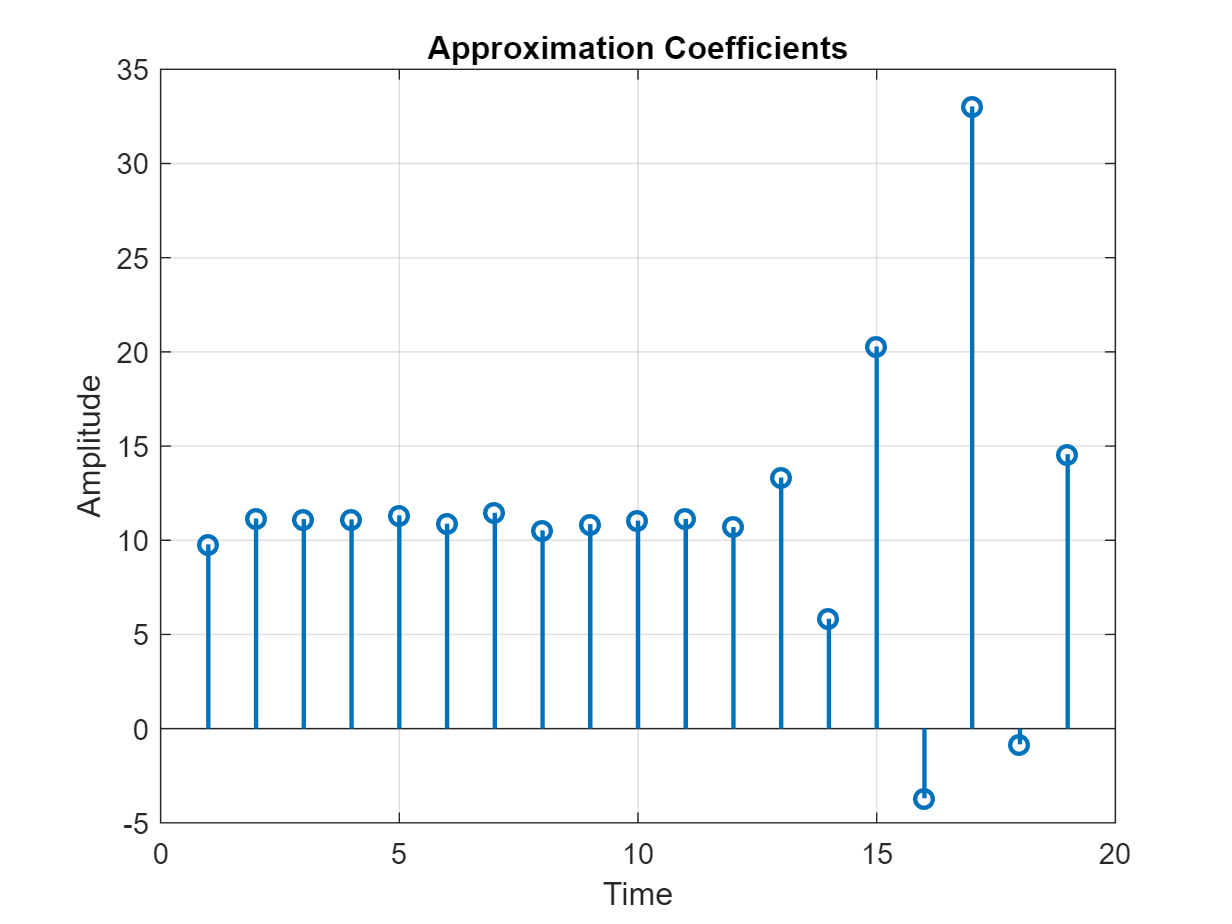

approx_coeff = appcoef(waveletCoefficients, waveletLevels, 'db10', numberOfLevels);
figure('Name', 'Approximation Coefficients');
stem(approx_coeff, 'LineWidth', 1.5);
title('Approximation Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;

### Part 7: Regenrate the wavelet coefficients from Approximation and Detail Coefficients

approx_coeff_deepest_layer = appcoef( ...
    waveletCoefficients, ...
    waveletLevels, ...
    'db10', ...
    numberOfLevels ...
);
wavelet_coefficients_regenerated = ...
    [approx_coeff_deepest_layer, detailed_coeff{numberOfLevels:-1:1}];
fprintf("\nError: %d\n", ...
    sum(abs(wavelet_coefficients_regenerated - waveletCoefficients)));


Error: 0


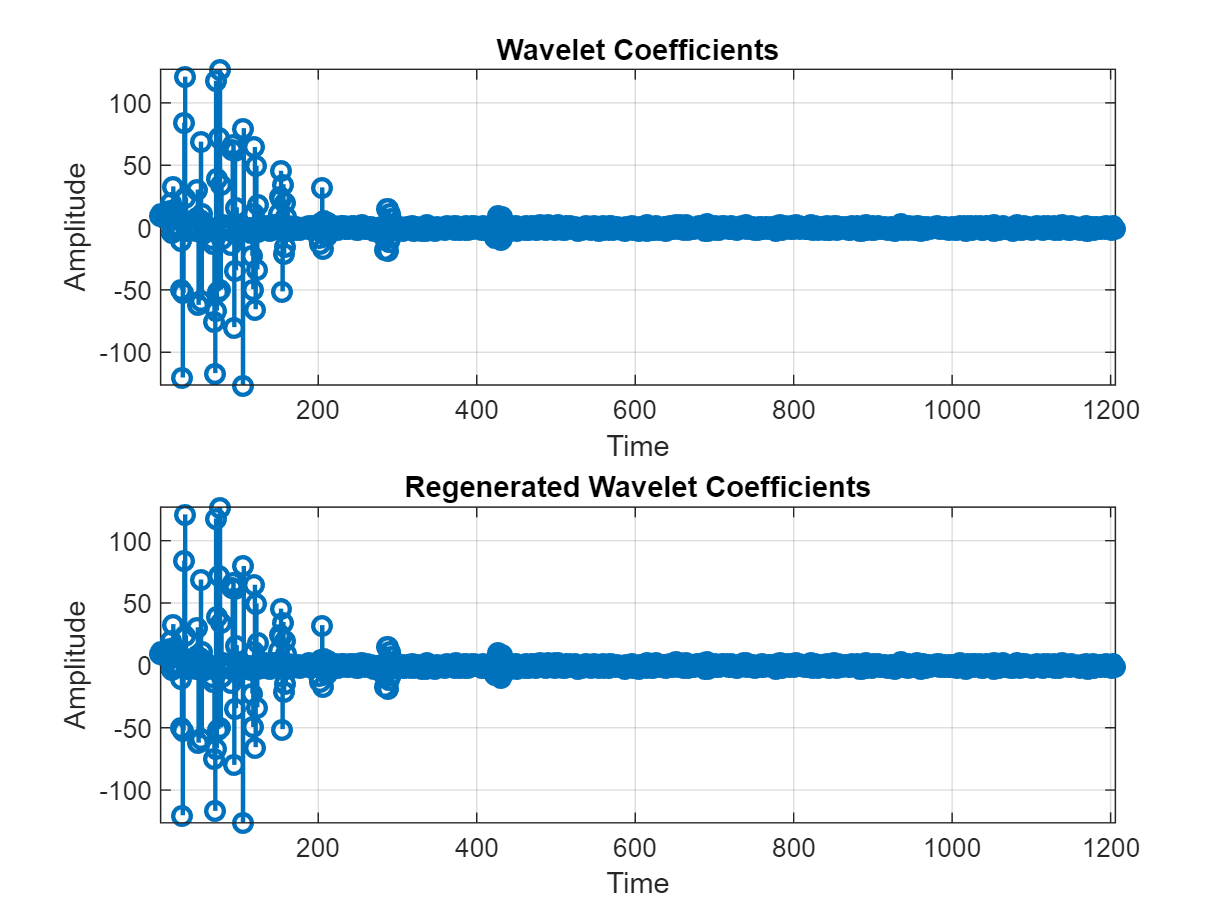

figure('Name', 'Wavelet Coefficients vs Regenerated Wavelet Coefficients');
subplot(211);
stem(waveletCoefficients, 'LineWidth', 1.5);
title('Wavelet Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;
subplot(212);
stem(wavelet_coefficients_regenerated, 'LineWidth', 1.5);
title('Regenerated Wavelet Coefficients');
xlabel('Time');
ylabel('Amplitude');
grid on;
axis tight;

### Part 8: Plot approximation coefficients

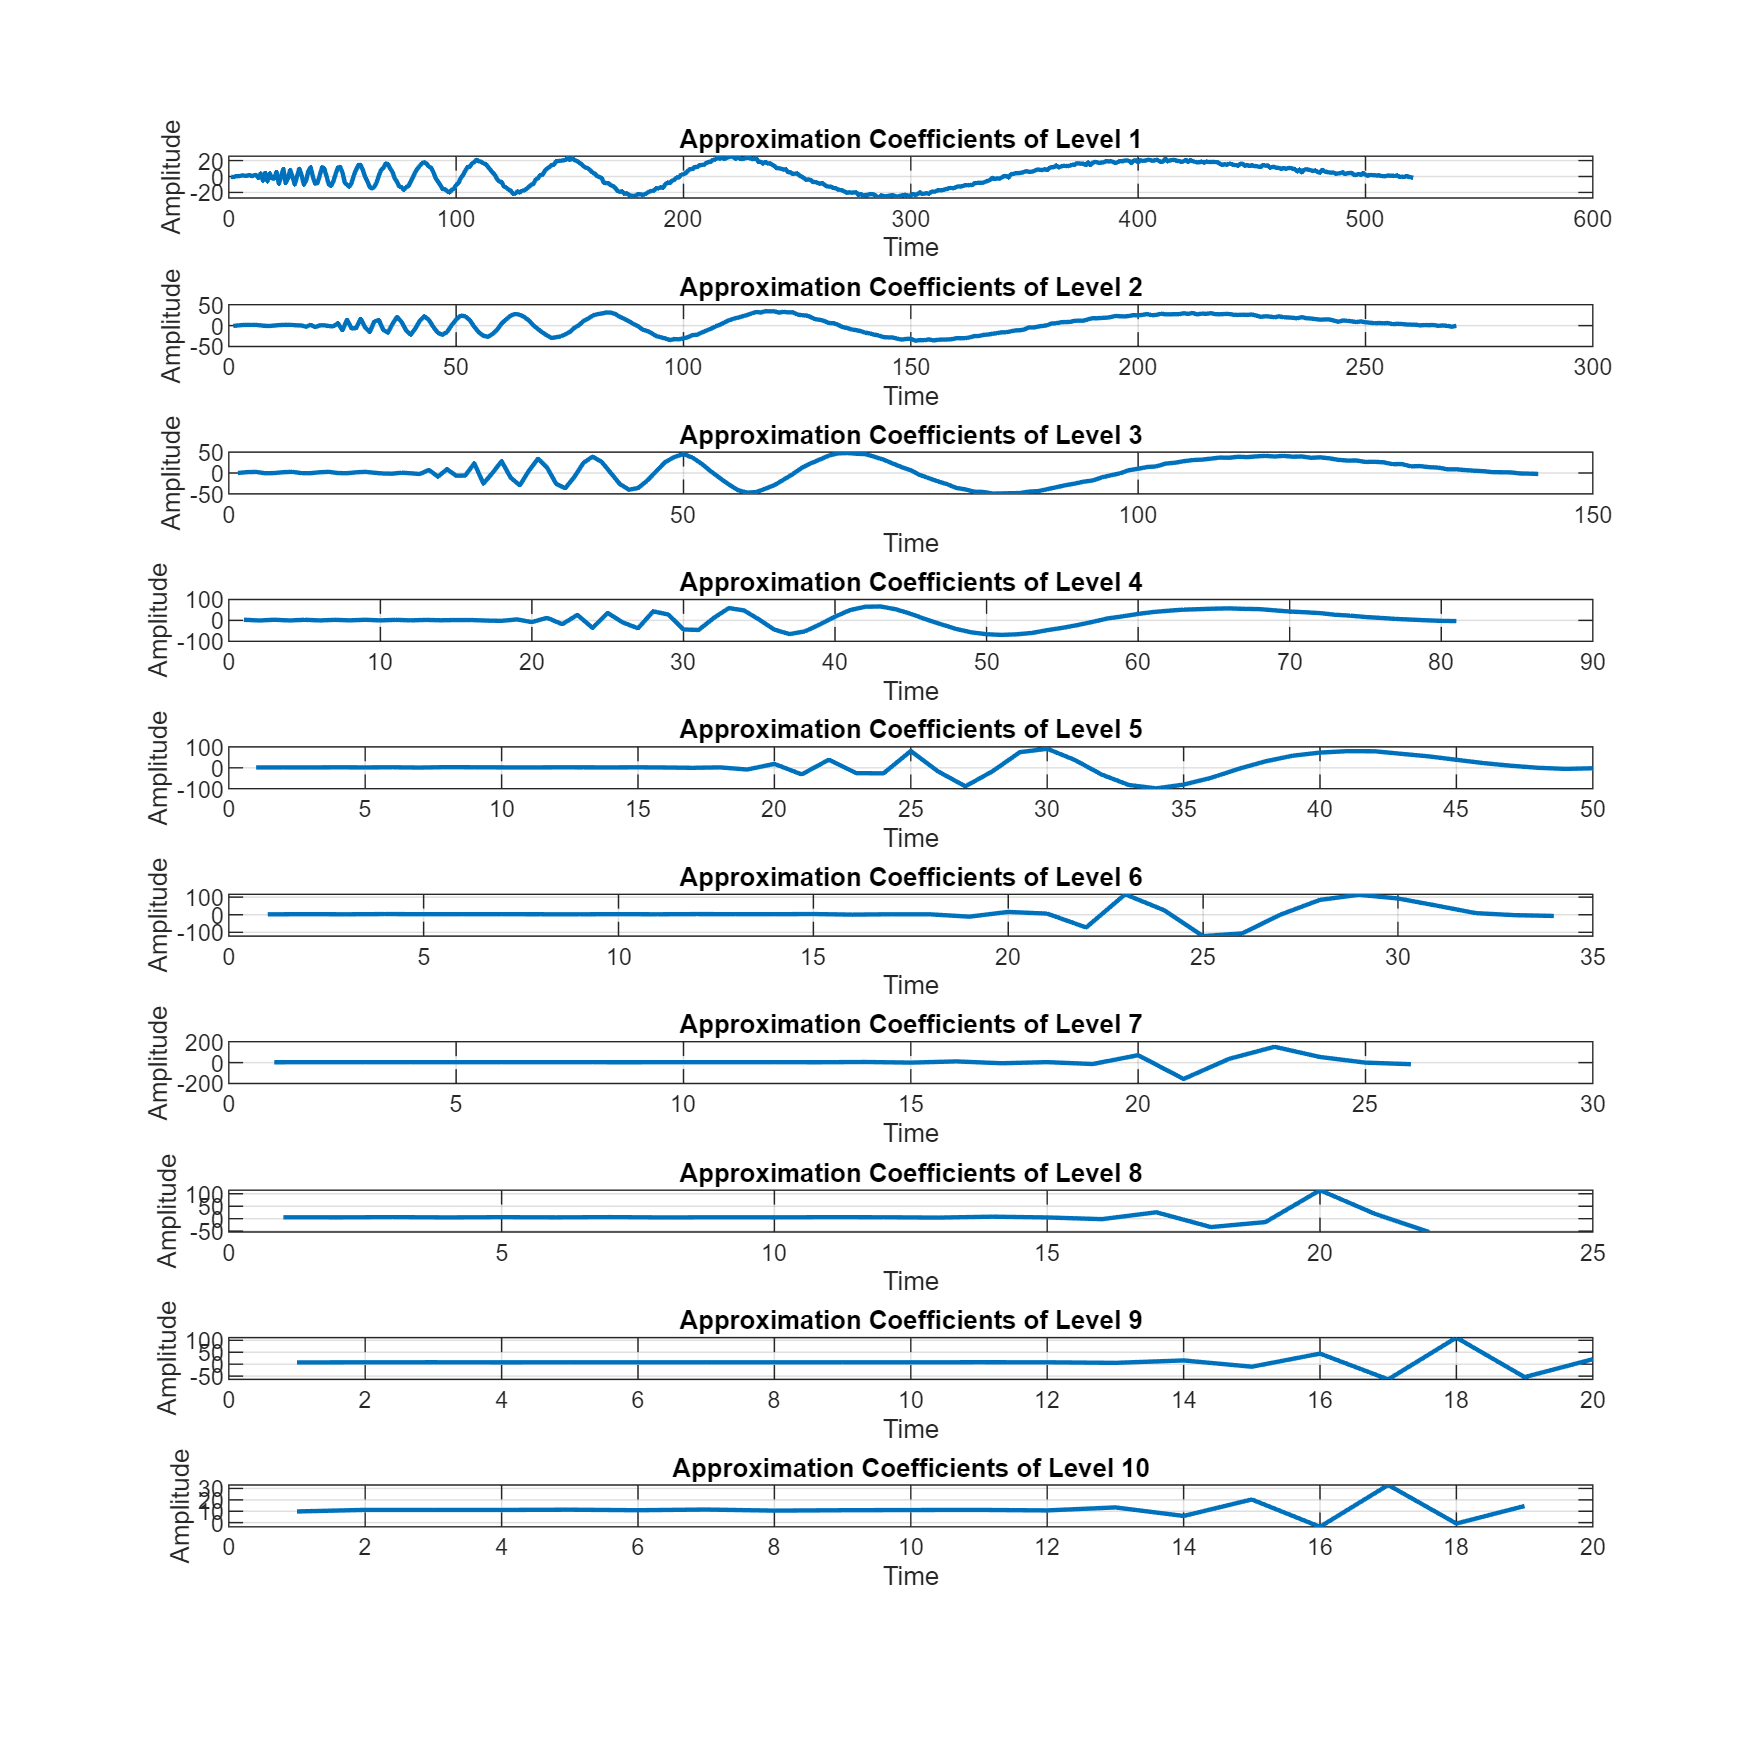

figure('Name', 'Approximation Coefficients of Different Levels');
set(gcf, 'Position', [100, 100, 1000, 1000]);

for i = 1:numberOfLevels
    approx_coeff = appcoef(waveletCoefficients, waveletLevels, 'db10', i);
    subplot(numberOfLevels, 1, i);
    plot(approx_coeff, 'LineWidth', 1.5);
    title(['Approximation Coefficients of Level ', num2str(i)]);
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

### Part 9: reconstruct the signal using waverec  

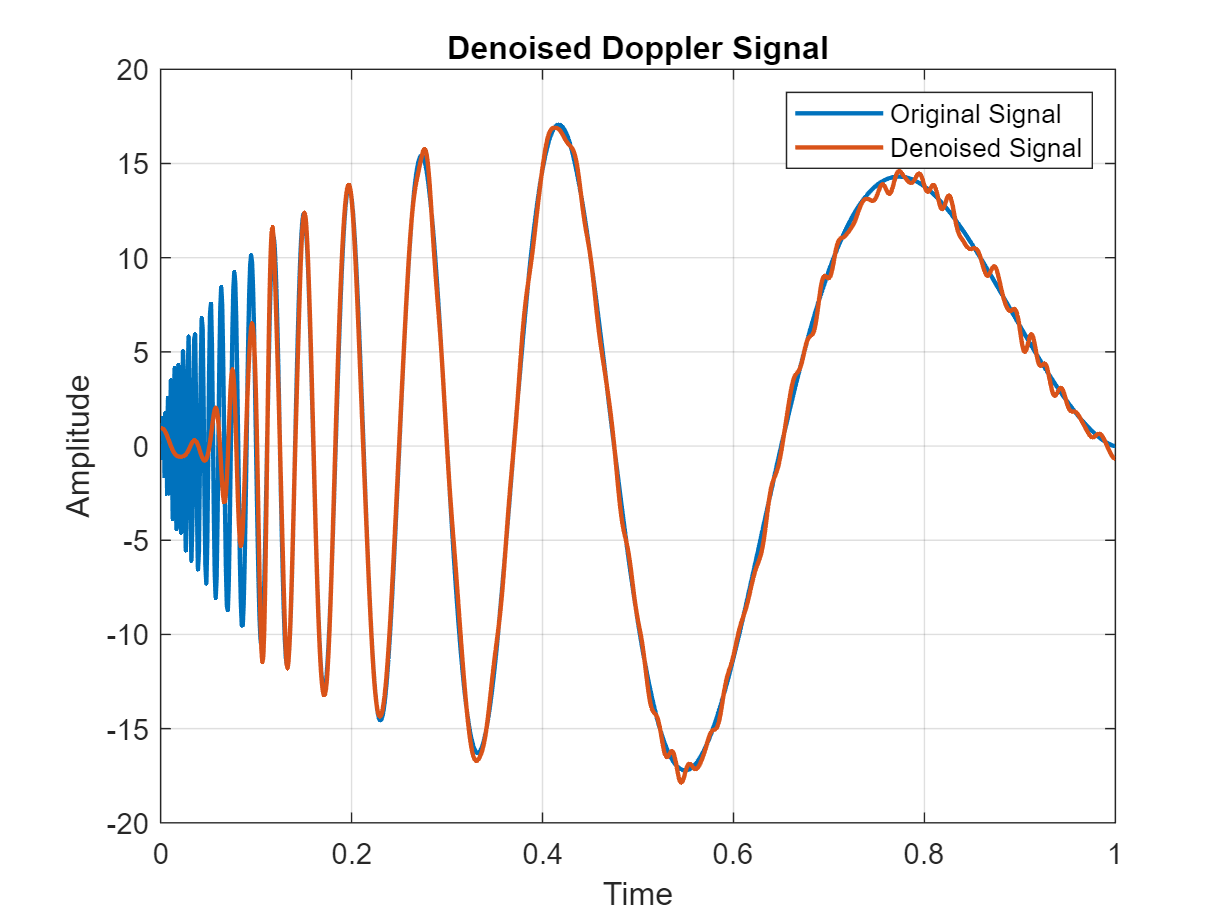

for level = 1:3
    detailed_coeff{level} = zeros(size(detailed_coeff{level}));
end

wavelet_coefficients_denoised = ...
    [approx_coeff_deepest_layer, detailed_coeff{numberOfLevels:-1:1}];

x_denoised = waverec(wavelet_coefficients_denoised, waveletLevels, 'db10');
figure('Name', 'Denoised Doppler Signal');
plot(loc, x, 'LineWidth', 1.5);
title('Denoised Doppler Signal');
xlabel('Time');
ylabel('Amplitude');
hold on;
grid on;
plot(loc, x_denoised, 'LineWidth', 1.5);
legend('Original Signal', 'Denoised Signal');

We can see that this method is reducing the noise but it is not the best method for denoising. In this signal By zeroing out levels 1–3 wholesale, we eliminate *all* of that high-frequency content. So, fast transitions before 0.1 sec are destroyed.

### Part 10:

### Functions

We used the following function to plot different plots with an arbitrary title:

function plot_dft_amp(x, fs, title_name)
    % Plots the amplitude spectrum of the signal x with sampling frequency fs
    % and title title_name.
    f_axis = linspace(-fs / 2, fs / 2, length(x));
    FT_x = fftshift(fft(x)) / fs;
    plot( ...
        f_axis, ...
        abs(FT_x), ...
        'LineWidth', ...
        1.5 ...
    );
    xlabel('Frequency(Hz)');
    title(title_name);
    ylabel('Amplitude');
    axis tight;
    grid on;
end